## **Mini-projet : Sujet MSure-k***

## **Etude de fiabilité pour un système en redondance passive**

*sujet : S4(k=4).*

k = 4;

Graphe de Markov : 

Pour établir le graphe de markov, il faut déja fixer les états, les transitions.

Les états seront les suivant : 

- f pour la file d'attente et F lorsqu’elle n'est pas fonctionnelle.

- c1 ->  **C1**

- C1 -> C1 en panne;

- c2 -> **C2 **

- C2 -> C2 est en panne.

Nous avons donc 3 composants, qui varient chacuns 2 fois. De plus chaque état est composé des 3 composants, ce qui nous donne 2^3 états 

Pour la matrice nous allons définir les états.

État 1 : fc1c2 

État 2 : Fc1c2 

État 3 : fC1c2 

État 4 : fc1C2 

État 5 : FC1c2 

État 6 : Fc1C2 

État 7 : fC1C2 

État 8 : FC1C2

La matrice sera donc, avec les données de l'énoncé : 

lambda1 =  taux de défaillance du buffer;

 mu1 = taux de réparation du buffer;

lambda2 = taux de défaillance c1 ou c2 

 mu2 = taux de réparation c1 ou c2.

gamma = refus de démarrer de c2.

Matrice de transition : 


$$\left\lbrack \begin{array}{cccccccc}
-\left(\lambda 1+\lambda 2\right) & \lambda 1 & 0 & \lambda 2 & 0 & 0 & 0 & 0\\
\mu 1 & -\mu 1 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & -\left(\mu 1+2*\;\mu 2\right) & 0 & \mu 1 & \mu 2 & \mu 2 & 0\\
\mu 2 & 0 & 0 & -\left(\lambda 1+\mu 2+\lambda 2\left(1-\gamma \right)+\gamma \right) & \lambda 2\left(1-\gamma \right)+\gamma  & \lambda 1 & 0 & 0\\
0 & 0 & \lambda 1 & \mu 2 & -\left(\lambda 1+2*\mu 2\right) & 0 & 0 & \mu 2\\
0 & \mu 2 & 0 & \mu 1 & 0 & -\left(\mu 1+\mu 2\right) & 0 & 0\\
0 & \mu 2 & 0 & 0 & 0 & 0 & -\left(\mu 1+\mu 2\right) & \mu 1\\
\mu 2 & 0 & 0 & 0 & \lambda 2 & 0 & \lambda 1 & -\left(\lambda 1+\lambda 2+\mu 2\right)
\end{array}\right\rbrack$$


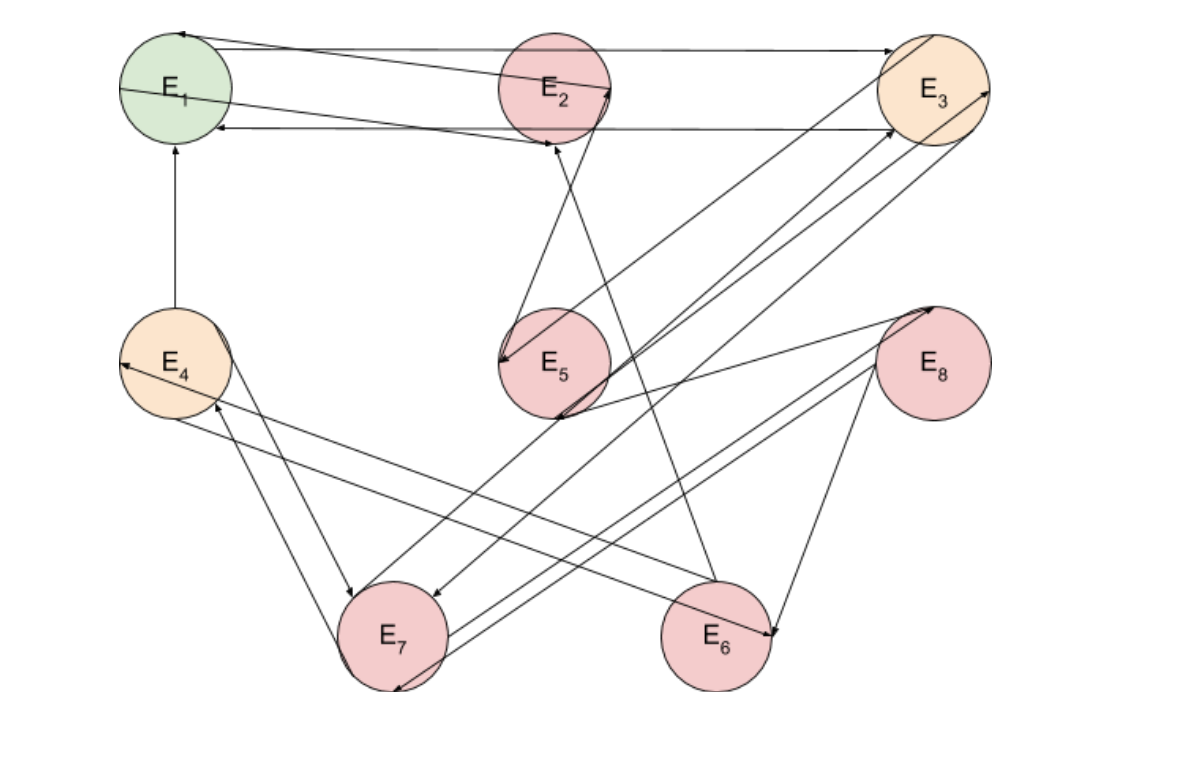

figure
imshow("graph.png")

Partie 1.2

Simulation : 

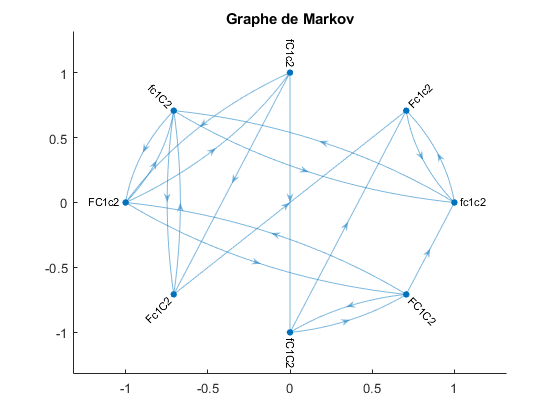

lambda1 = 0.01 * k;
lambda2 = 0.02 * k;
mu1 = 0.015;
mu2 = 0.03;
gamma = 0.4;

matrice_transition = [
    -(lambda1 + lambda2) lambda1 0 lambda2 0 0 0 0; 
    mu1 -mu1 0 0 0 0 0 0;
    0 0 -(mu1 + 2 * mu2) 0 mu1 mu2 mu2 0;
    mu2 0 0 -(lambda1+mu2+lambda2*(1-gamma)+gamma) lambda2*(1-gamma)+gamma lambda1 0 0;
    0 0 lambda1 mu2 -(lambda1 + 2 * mu2) 0 0 mu2;
    0 mu2 0 mu1 0 -(mu1 + mu2) 0 0;
    0 mu2 0 0 0 0 -(mu1 + mu2) mu1;
    mu2 0 0 0 lambda2 0 lambda1 -(lambda1 + lambda2 + mu2)    
    ];


nodes= ["fc1c2", "Fc1c2" , "fC1c2" , "fc1C2" , "FC1c2" , "Fc1C2", "fC1C2", "FC1C2"];
G = digraph(matrice_transition,nodes,'omitselfloops');
figure

hold on;
plot(G,'Layout','circle');
title('Graphe de Markov');
hold off;

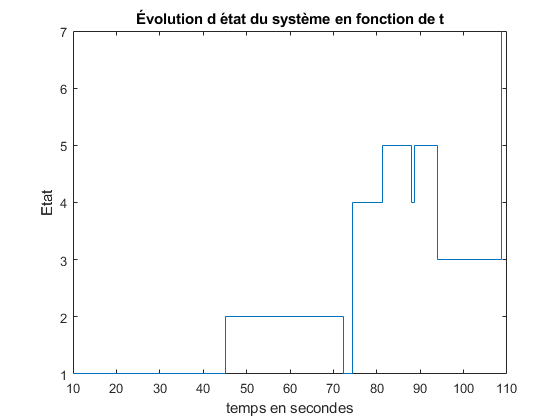


%Il faut ensuite initialiser un état inital.
P0 = [1 0 0 0 0 0 0 0];
%simulation 
t = 100;
l1=lambda1;
l2 = lambda2;
g = gamma;
u2 = mu2;
u1 = mu1;
[X,S] = CMTC(P0,matrice_transition,t);
figure
stairs(S,X);
hold on;
xlabel('temps en secondes')
ylabel('Etat')
title('Évolution d état du système en fonction de t' )

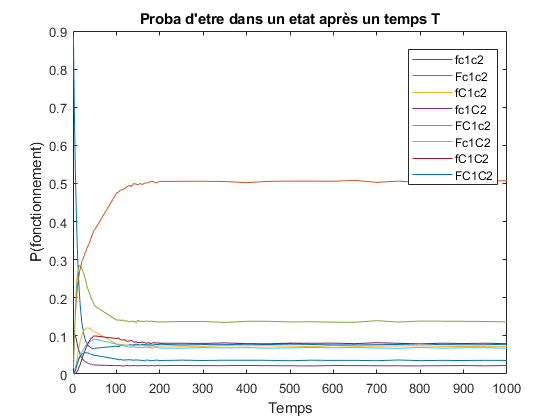

%Nous allons étudier le comportement avec des t qui varient
resultat = [];
T = [1:1:50,100:5:200,250:50:1000];
N = 100000;

variation_du_temps = cell2mat(arrayfun(@(x) Pi(x,N,P0,matrice_transition),T,'UniformOutput',false));
%arrayfun : Apply function to each element of array 
figure;
plot(T,variation_du_temps);
hold on
legend({'fc1c2', 'Fc1c2' , 'fC1c2' , 'fc1C2' , 'FC1c2' , 'Fc1C2', 'fC1C2', 'FC1C2'},'Location','best')
xlabel('Temps')
ylabel('P(fonctionnement)')
title('Proba d''etre dans un etat après un temps T')
hold off

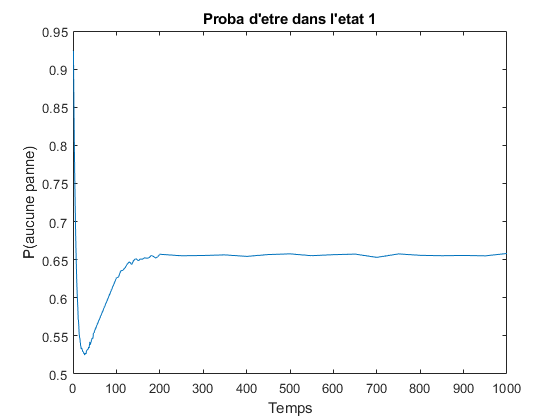

Rt = variation_du_temps(1,:)+variation_du_temps(2,:)+variation_du_temps(3,:);
figure;
plot(T,Rt);
hold on;
xlabel('Temps')
ylabel('P(aucune panne)')
title('Proba d''etre dans l''etat 1')
hold off;

EtatsErreur = [1 0 1 1 0 0 0 0];
MTTF(N,P0,matrice_transition,EtatsErreur)

ans = 40.3630

MDT(N,P0,matrice_transition,EtatsErreur,t)

ans = 58.2859

Simulation avec un gamma qui varie entre 0 & 1 avec un pas de 0.1

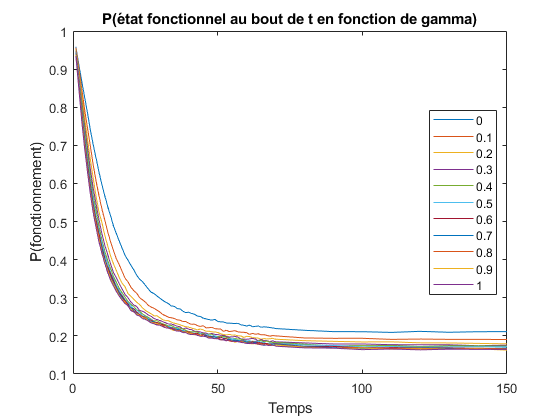

g = 0:0.1:1;
temps = [1:1:70,80:10:150];
probas = cell2mat(arrayfun(@(x) gamma_change(x,temps,N), g, 'UniformOutput',false));
figure;
plot(temps,probas.');
hold on
legend({'0','0.1','0.2','0.3','0.4','0.5','0.6','0.7','0.8','0.9','1'},'Location','best')
xlabel('Temps')
ylabel('P(fonctionnement)')
title(['P(état fonctionnel au bout de t en fonction de gamma)'])
hold off;